**读取minflux数据**

close all;clear;clc;
flag1 = false;
flag2 = 'true';
flag3 = false;
path = '/Users/WangHao/Desktop/未命名文件夹/1016 Alex 647 alpha-tublin DL M4 .msr.npy.mat';
data = load(path);
loc = data.loc;
tid = data.tid;

**绘制散点图**

   1.0e-05 *

   -0.1988    0.2008
   -0.2174    0.2178
   -0.0681    0.0797



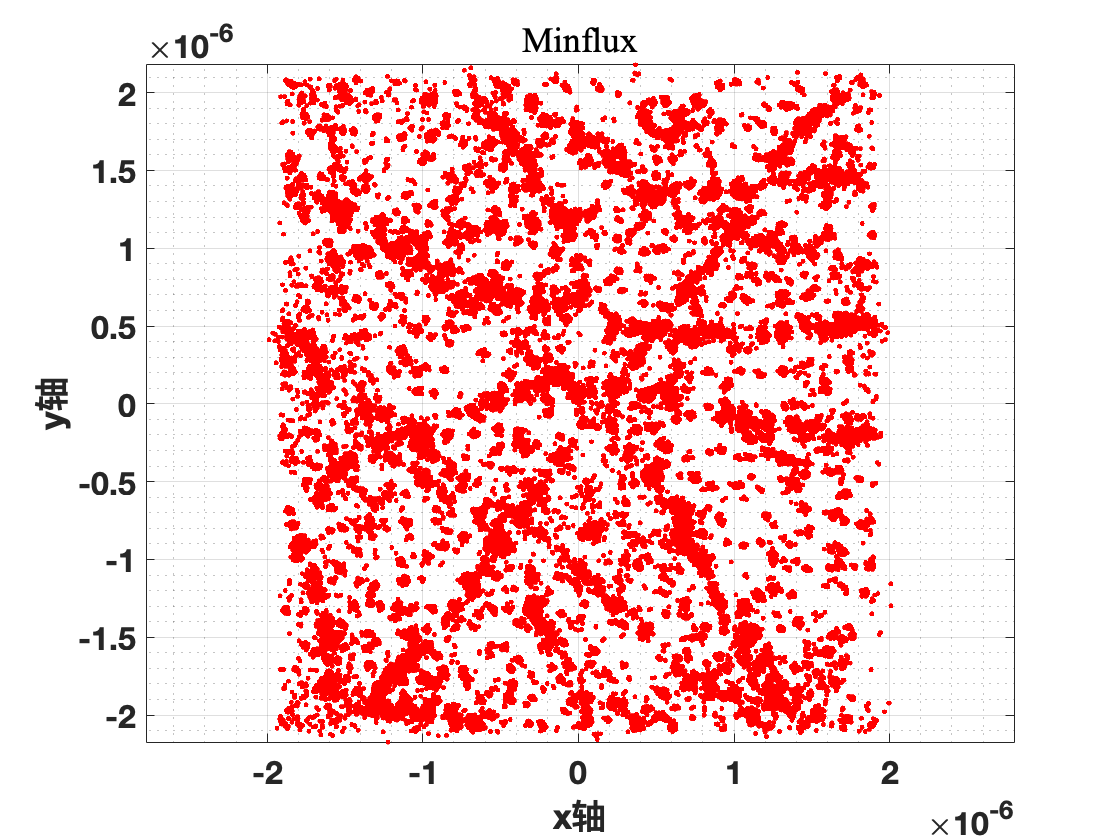

if size(loc, 2) == 3
    result_max = max(loc, [], 1);
    x_max = result_max(1, 1);
    y_max = result_max(1, 2);
    z_max = result_max(1, 3);
    
    result_min = min(loc, [], 1);
    x_min = result_min(1, 1);
    y_min = result_min(1, 2);
    z_min = result_min(1, 3);
    
    disp([x_min, x_max; y_min, y_max; z_min, z_max])
    
    f = figure;
    X = loc(:, 1);
    Y = loc(:, 2);
    Z = loc(:, 3);    
    scatter3(X, Y, Z, 'r.');
    
    box on
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('Minflux', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    view([0, 0, 1])
    axis equal
else
    result_max = max(loc, [], 1);
    x_max = result_max(1, 1);
    y_max = result_max(1, 2);
    
    result_min = min(loc, [], 1);
    x_min = result_min(1, 1);
    y_min = result_min(1, 2);
    
    disp([x_min, x_max; y_min, y_max])
    
    f = figure;
    X = loc(:, 1);
    Y = loc(:, 2);  
    scatter3(X, Y, 'b.');
    
    box on
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    title('Minflux', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    view([0, 0, 1])
    axis equal
end

**滑窗选中区域**

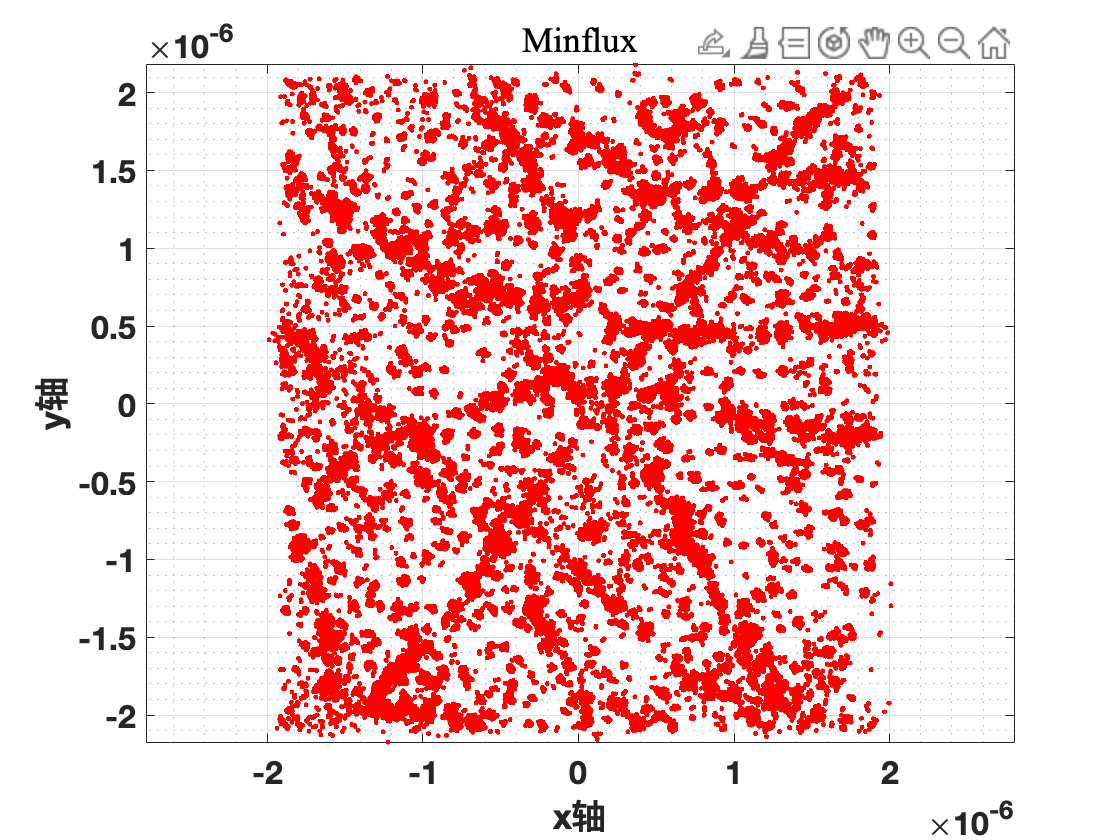

rect = getrect(gcf);

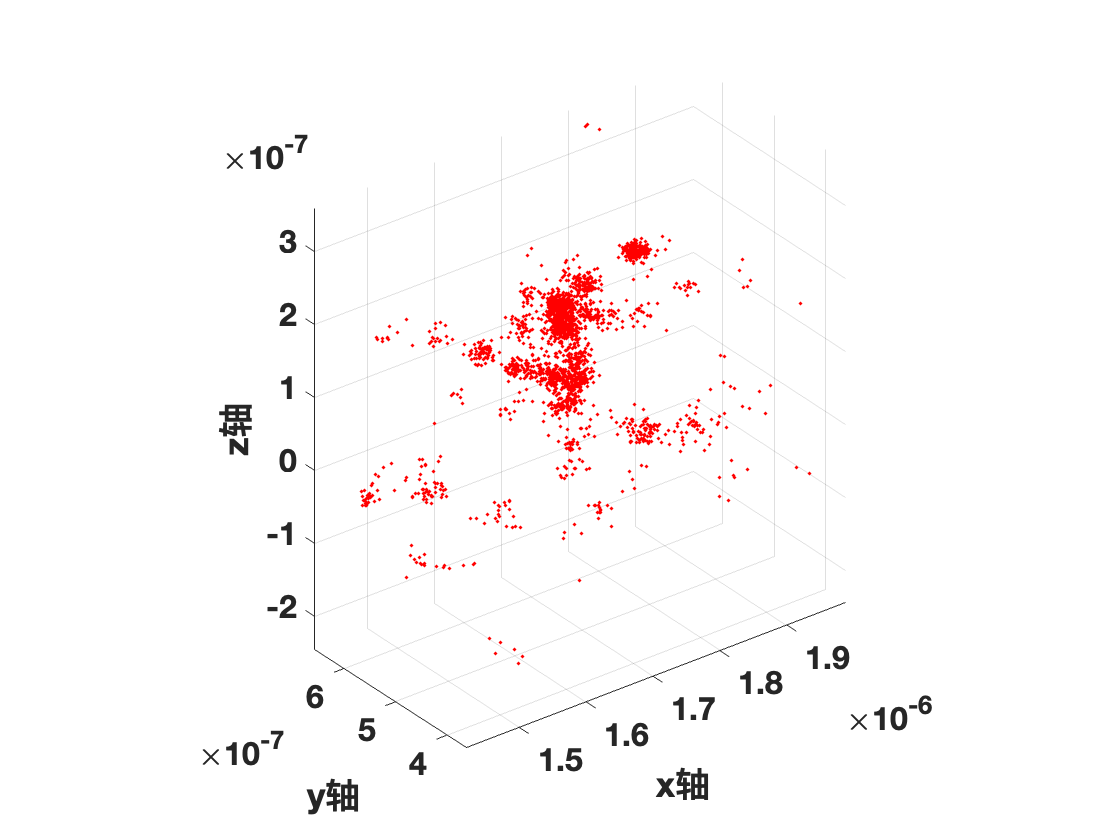

x1 = rect(1);
x2 = x1+rect(3);
y1 = rect(2);
y2 = y1+rect(4);
aim = find(loc(:, 1)>x1 & loc(:, 1)<x2 & loc(:, 2)>y1 & loc(:, 2)<y2);
if size(loc, 2) == 3
    f1 = figure;
    X1 = loc(aim, 1);
    Y1 = loc(aim, 2);
    Z1 = loc(aim, 3);    
    scatter3(X1, Y1, Z1, 5, [1, 0, 0], 'filled');
    z1 = min(loc(aim, 3), [], 'all');
    z2 = max(loc(aim, 3), [], 'all');
    axis([x1, x2, y1, y2, z1, z2]*1.05);
    xlabel('x轴');
    ylabel('y轴');
    zlabel('z轴');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    axis equal
    loc = [loc(aim, 1), loc(aim, 2), loc(aim, 3)];
    tid = tid(aim, 2);
elseif size(loc, 2) == 2
    f1 = figure;
    X1 = loc(aim, 1);
    Y1 = loc(aim, 2);    
    scatter3(X1, Y1, 5, [0, 0, 1], 'filled');
    axis([x1, x2, y1, y2]*1.05);
    xlabel('x轴'); 
    ylabel('y轴');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    axis equal
    loc = [loc(aim, 1), loc(aim, 2)];
    tid = tid(aim, 2);
end

**DBSCAN去噪**

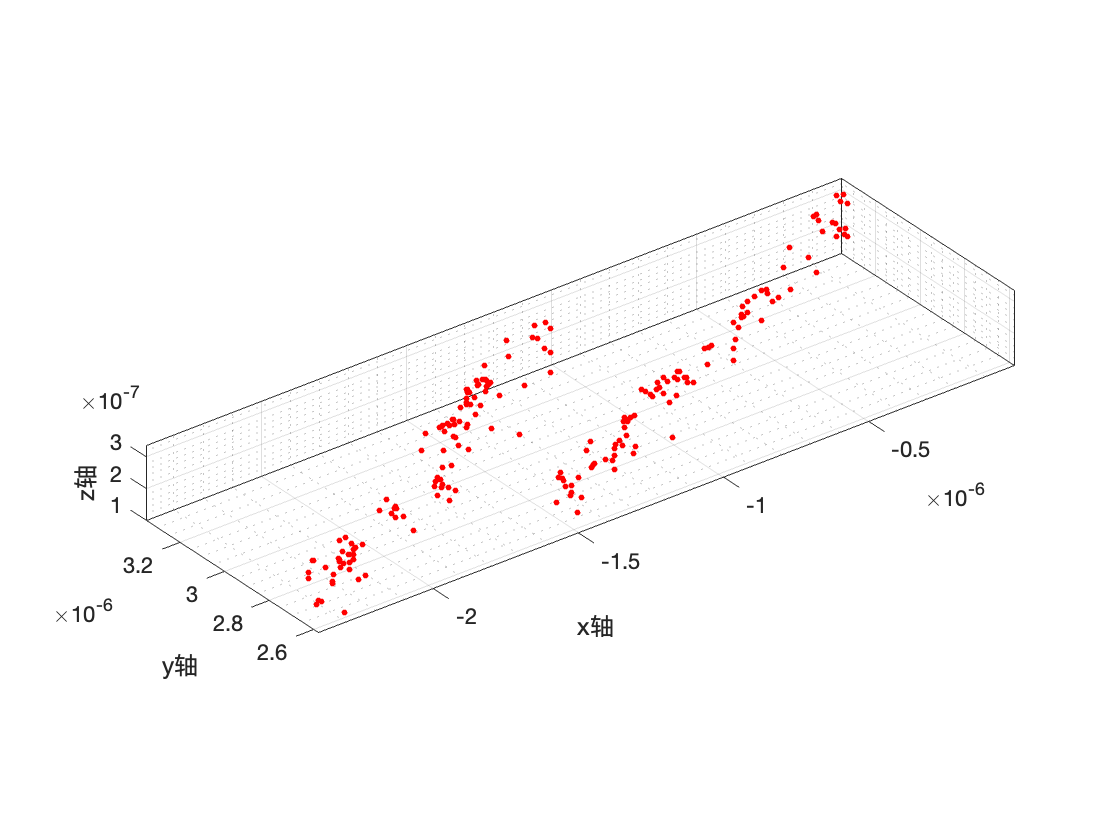

eps = 10e-8;
minpts = 5;
cluster = GetCluster(loc, eps, minpts);
area = 10;
noise = false;
kind = size(cluster, 2);

temp1 = [];
temp2 = [];
figure;
for j = 1 : kind
    if j < kind
        ClusterP = cluster{j};
        k = ClusterP';
        temp1 = [temp1; loc(k, :)];
        temp2 = [temp2; tid(k)];
        scatter3(loc(k, 1), loc(k, 2), loc(k, 3), area, [1 ,0 ,0], 'filled');
        hold on;
    elseif j == kind && noise
        ClusterP = cluster{j};
        k = ClusterP';
        temp1 = [temp1; loc(k, :)];
        temp2 = [temp2; tid(k)];
        scatter3(loc(k, 1), loc(k, 2), loc(k, 3), area, [0 ,0 ,0], 'filled');
        hold off;
    end
end

if ~isempty(temp1)
    loc = temp1;
end
if ~isempty(temp2)
    tid = temp2;
end

box on
xlabel('x轴')
ylabel('y轴')
zlabel('z轴')
set(gca, 'xgrid', 'on');
set(gca, 'ygrid', 'on');
set(gca, 'zgrid', 'on');
set(gca, 'xminorgrid', 'on');
set(gca, 'yminorgrid', 'on');
set(gca, 'zminorgrid', 'on');
axis equal

**过滤重复tid点**

mode = 0;

uq_tid = unique(tid);
j = 1;
temp = [];
for i = 1 : length(tid)
    x(i, 1) = find(uq_tid == tid(i));
    if j == x(i, 1)
        temp = [temp; loc(i, :)]; 
    else
        loc_mean(j, :) = mean(temp, 1);
        temp = loc(i, :);
        j = j + 1;
    end
end

if j == max(x)
    loc_mean(j, :) = mean(temp, 1);
end

j = 1;
for i = 1 : length(tid)
    x(i, 1) = find(uq_tid == tid(i));
    if j == x(i, 1)
        loc_start(j, :) = loc(i, :);
        j = j + 1;
    end
end

if mode == 0
    loc = loc_mean;
else
    loc = loc_start;
end
tid = uq_tid;

**tid顺序着色和z轴高度着色**

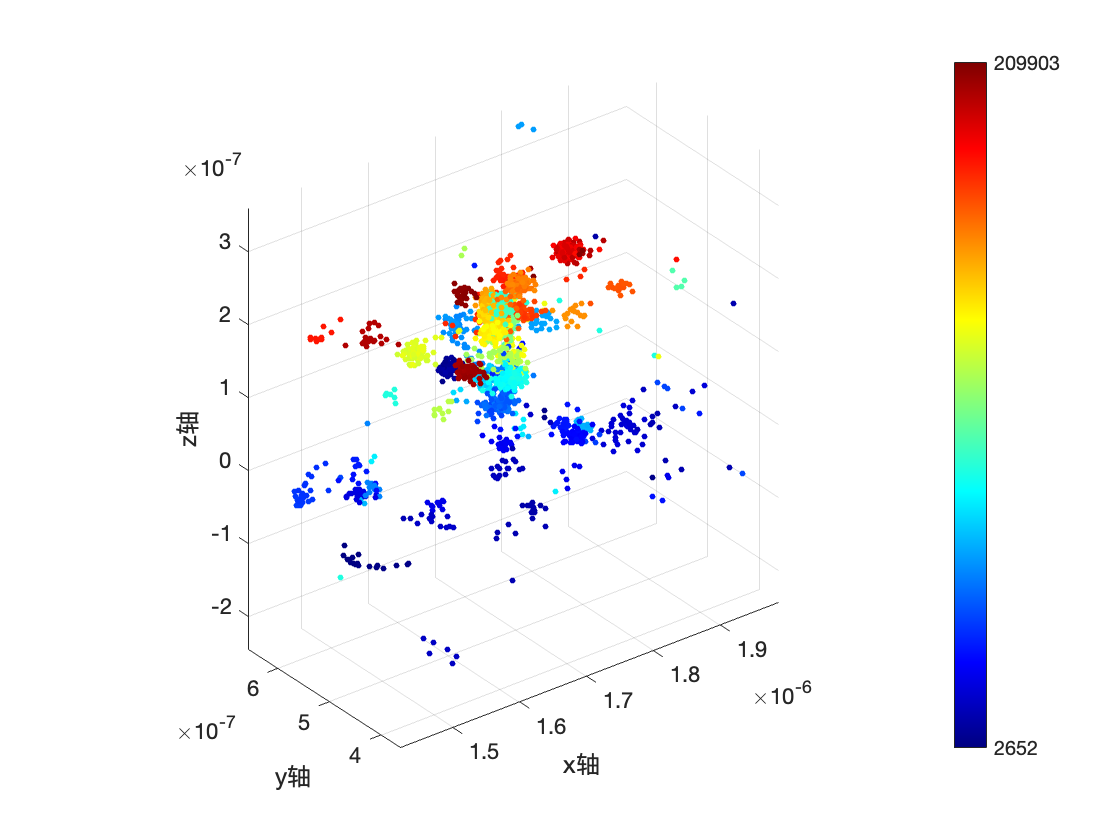

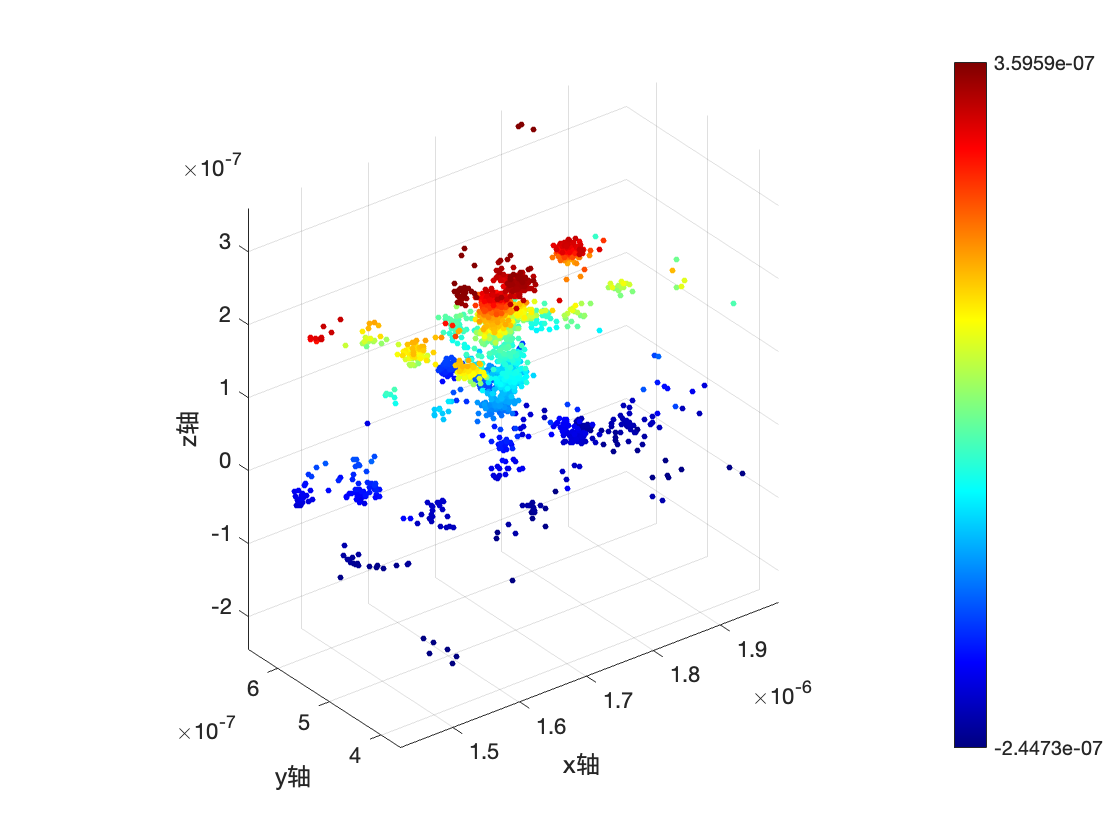

uq_tid = unique(tid);
uq_tid = tid;
l = length(uq_tid)/8+1;
map1 = [linspace(0,0,l)', linspace(0,0,l)', linspace(0.5,1,l)'];
map2 = [linspace(0,0,2*l)', linspace(0,1,2*l)', linspace(1,1,2*l)'];
map3 = [linspace(0,1,2*l)', linspace(1,1,2*l)', linspace(1,0,2*l)'];
map4 = [linspace(1,1,2*l)', linspace(1,0,2*l)', linspace(0,0,2*l)'];
map5 = [linspace(1,0.5,l)', linspace(0,0,l)', linspace(0,0,l)'];
cmap = cat(1, map1, map2, map3, map4, map5);

c = (1 : length(tid))';
if size(loc, 2) == 3
    
    f2 = figure;
    X2 = loc(:, 1);
    Y2 = loc(:, 2);
    Z2 = loc(:, 3);    
    scatter3(X2, Y2, Z2, 10, cmap(c, :), 'filled');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    axis equal
    colormap(cmap)
    colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(tid)), num2str(max(tid))});

    [b1, i1] = sort(loc(:, 3));
    f3 = figure;
    X3 = loc(i1, 1);
    Y3 = loc(i1, 2);
    Z3 = loc(i1, 3); 
    scatter3(X3, Y3, Z3, 10, cmap(c, :), 'filled');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    axis equal
    colormap(cmap)
    colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(loc(:, 3))), num2str(max(loc(:, 3)))});
end